clear
clc

addpath("functions\")

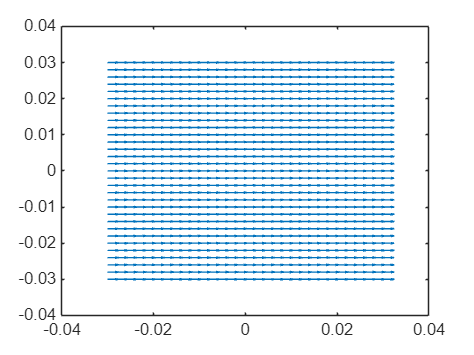

coil = struct('type','Arbitrary', 'Brho',@Brho_func);
% coil = struct('type','MagneticSensor', 'position',[18e-3 0 0], 'axis',[1 0 0]);
pipe = struct('sigma',3.774e5, 'mur',1, 'inner_diameter',40e-3, 'outer_diameter',46e-3);

model = CoilInsidePipe(coil, pipe);

rho = 43e-3 / 2;
z = linspace(-30e-3, 30e-3, 31);
phi = z / rho;
[phi, z] = ndgrid(phi, z);
rho = rho * ones(size(z));

[Ephi, Ez] = model.EvaluateField({'Ephi' 'Ez'}, rho,phi,z, 2*pi*200);

figure
quiver(phi.*rho, z, imag(Ephi), imag(Ez))

function Brho = Brho_func(rho, phi, z)

[x,y,z] = pol2cart(phi,rho,z);

x_ = x; y_ = -z; z_ = y - 10e-3;
[theta_,r_,z_] = cart2pol(x_,y_,z_);
B_ = CoilField('MFD', 5e-3, 10e-3, 5e-3, 100, r_, z_);
Bx_ = B_(1) * cos(theta_);
By_ = B_(1) * sin(theta_);
Bz_ = B_(2);

Bx = Bx_;
By = Bz_;
Bz = -By_;
Brho = Bx * cos(phi) + By * sin(phi);

end